- **Use the Hanning, rectangular and Hamming tapers to compute spectra**

The frequency spectra has been plotted below for all the functions.

Hamming window has maximum overlapping of the spectra.

Hanning window has least overlapping spectra.

**2.   What is the sampling frequency in relation to Nyquist sampling theorem?**

In relation to the Nyquist sampling theorem, the sampling frequency should be atleast double of the maximum frequency of the signal. The sampling frequency in relation to Nyquist sampling theorem for each signal is given below.

## **Defining Windows**

Window_h=hann(5);
Window_Hm=hamming(5)

Window_Hm =     0.0800
    0.5400
    1.0000
    0.5400
    0.0800


Window_R = rectwin(5);

## **Sine**

t = 0 : 1/1000 : 1;
f1 = 5; 
T1 = 1/f1;
amp1 = 1; 
signal = amp1 * sin(2*pi*t/T1);
%Hann
Y=fft(signal.*Window_h);
L = length (signal);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

P1(2:end-1) = 2*P1(2:end-1);
f = 1000*(0:(L/2))/L;
subplot (3,1,1)
plot(f,P1) 
title('Single-Sided Freq Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|X(f)|')
%Ham
Y=fft(signal.*Window_Hm);
L = length (signal);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

P1(2:end-1) = 2*P1(2:end-1);
f = 1000*(0:(L/2))/L;
subplot (3,1,2)
plot(f,P1) 
title('Single-Sided Freq Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|X(f)|')
%Rect
Y=fft(signal.*Window_R);
L = length (signal);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

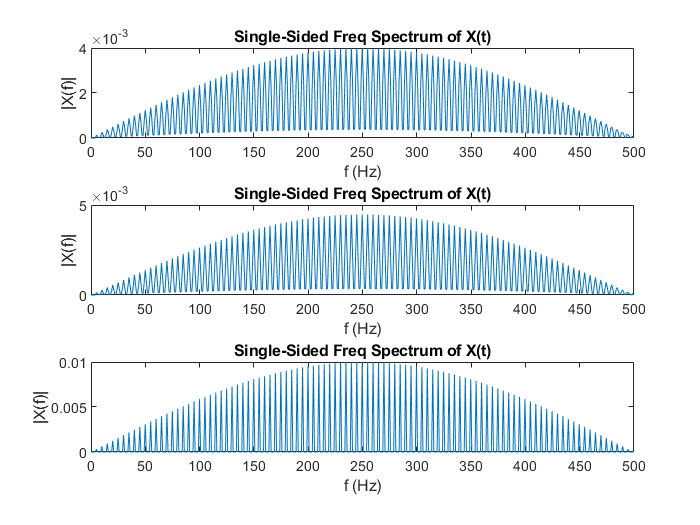

P1(2:end-1) = 2*P1(2:end-1);
f = 1000*(0:(L/2))/L;
subplot (3,1,3)
plot(f,P1) 
title('Single-Sided Freq Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|X(f)|')

Sampling Frequency in relation to Nyquist sampling theorem : 10Hz

## **Log Chirp**

t= 0:0.001:10; 
signal=chirp(t,10,10,400,'logarithmic');

%Hann
Y=fft(signal.*Window_h);
L = length (signal);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

P1(2:end-1) = 2*P1(2:end-1);
f = 1000*(0:(L/2))/L;
subplot (3,1,1)
plot(f,P1) 
title('Single-Sided Freq Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|X(f)|')
%Ham
Y=fft(signal.*Window_Hm);
L = length (signal);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

P1(2:end-1) = 2*P1(2:end-1);
f = 1000*(0:(L/2))/L;
subplot (3,1,2)
plot(f,P1) 
title('Single-Sided Freq Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|X(f)|')
%Rect
Y=fft(signal.*Window_R);
L = length (signal);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

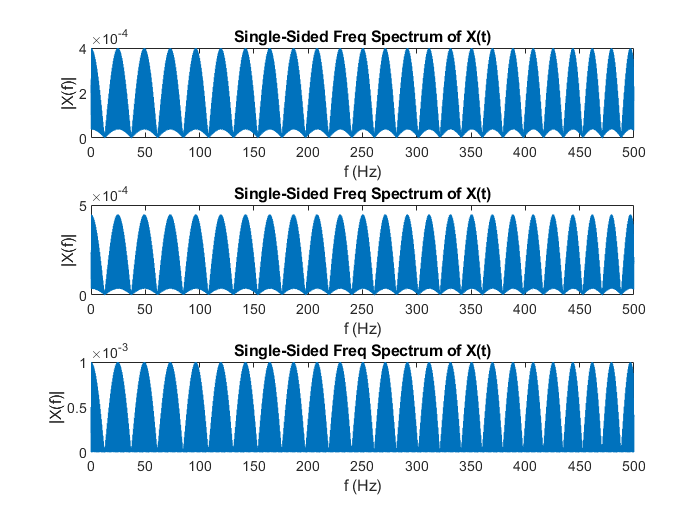

P1(2:end-1) = 2*P1(2:end-1);
f = 1000*(0:(L/2))/L;
subplot (3,1,3)
plot(f,P1) 
title('Single-Sided Freq Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|X(f)|')

Sampling Frequency in relation to Nyquist sampling theorem : 800Hz

## Quadratic Chirp

t=-2:0.001:2;                  
signal=chirp(t,10,1,100,'q'); 

%Hann
Y=fft(signal.*Window_h);
L = length (signal);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

P1(2:end-1) = 2*P1(2:end-1);
f = 1000*(0:(L/2))/L;
subplot (3,1,1)
plot(f,P1) 
title('Single-Sided Freq Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|X(f)|')
%Ham
Y=fft(signal.*Window_Hm);
L = length (signal);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

P1(2:end-1) = 2*P1(2:end-1);
f = 1000*(0:(L/2))/L;
subplot (3,1,2)
plot(f,P1) 
title('Single-Sided Freq Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|X(f)|')
%Rect
Y=fft(signal.*Window_R);
L = length (signal);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

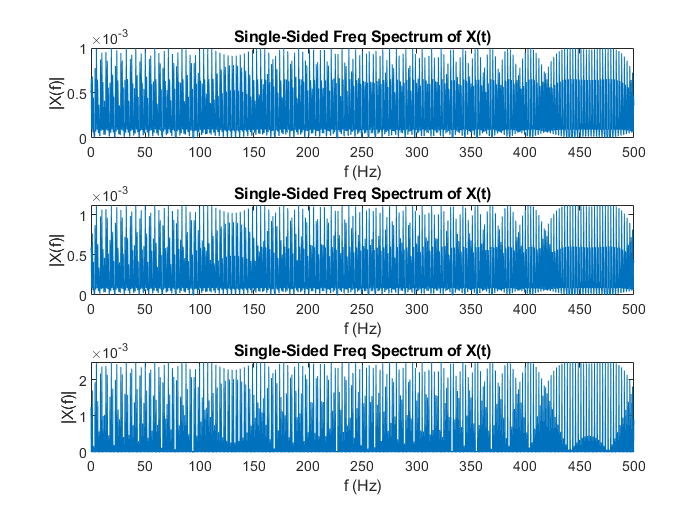

P1(2:end-1) = 2*P1(2:end-1);
f = 1000*(0:(L/2))/L;
subplot (3,1,3)
plot(f,P1) 
title('Single-Sided Freq Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|X(f)|')

Sampling Frequency in relation to Nyquist sampling theorem : 200Hz

## Linear Chirp

t=0:0.001:2; 
signal=chirp(t,0,1,150);  

%Hann
Y=fft(signal.*Window_h);
L = length (signal);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

P1(2:end-1) = 2*P1(2:end-1);
f = 1000*(0:(L/2))/L;
subplot (3,1,1)
plot(f,P1) 
title('Single-Sided Freq Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|X(f)|')
%Ham
Y=fft(signal.*Window_Hm);
L = length (signal);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

P1(2:end-1) = 2*P1(2:end-1);
f = 1000*(0:(L/2))/L;
subplot (3,1,2)
plot(f,P1) 
title('Single-Sided Freq Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|X(f)|')
%Rect
Y=fft(signal.*Window_R);
L = length (signal);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

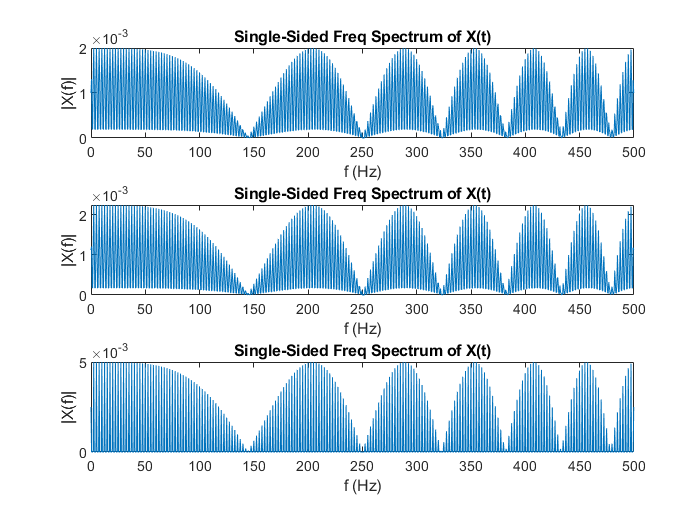

P1(2:end-1) = 2*P1(2:end-1);
f = 1000*(0:(L/2))/L;
subplot (3,1,3)
plot(f,P1) 
title('Single-Sided Freq Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|X(f)|')

Sampling Frequency in relation to Nyquist sampling theorem : 300Hz

## Concave Chirp

t= 0:0.0001:2;
y=chirp(t,100,1,25,'q',[],'concave');

%Hann
Y=fft(signal.*Window_h);
L = length (signal);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

P1(2:end-1) = 2*P1(2:end-1);
f = 1000*(0:(L/2))/L;
subplot (3,1,1)
plot(f,P1) 
title('Single-Sided Freq Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|X(f)|')
%Ham
Y=fft(signal.*Window_Hm);
L = length (signal);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

P1(2:end-1) = 2*P1(2:end-1);
f = 1000*(0:(L/2))/L;
subplot (3,1,2)
plot(f,P1) 
title('Single-Sided Freq Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|X(f)|')
%Rect
Y=fft(signal.*Window_R);
L = length (signal);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

P1(2:end-1) = 2*P1(2:end-1);
f = 1000*(0:(L/2))/L;
subplot (3,1,3)
plot(f,P1) 
title('Single-Sided Freq Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|X(f)|')

Sampling Frequency in relation to Nyquist sampling theorem : 200Hz